% 定义参数
fs = 1000; % 采样率
T = 1; % 信号持续时间（秒）
t = 0:1/fs:T-1/fs; 

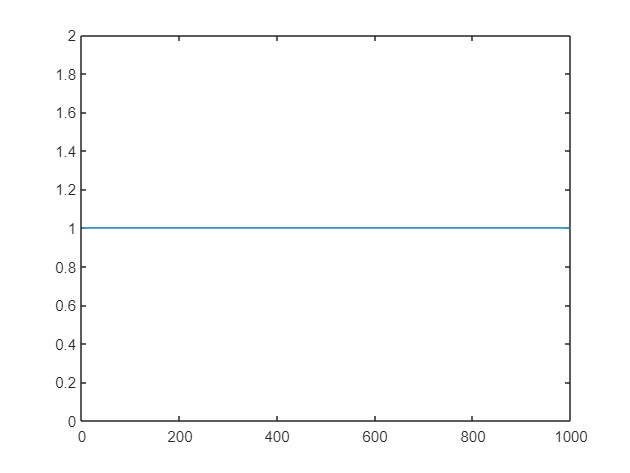


% 发送信号
normal_pulse = rectpuls(t - T/2, T); % 普通带宽的矩形脉冲
chirp_pulse = chirp(t, 100, T, 200); % Chirp信号

% 模拟接收到的回波信号（添加噪声）
noise =  0.2 * randn(size(t));
received_normal = normal_pulse + noise; % 普通带宽脉冲的回波
received_chirp = chirp_pulse + 0.2 * noise; % Chirp信号的回波

% 匹配滤波器
matched_filter = fliplr(chirp_pulse); % 匹配滤波器为Chirp信号的翻转

% 使用匹配滤波器处理回波信号
output_normal = conv(received_normal, matched_filter, 'same');
output_chirp = conv(received_chirp, matched_filter, 'same');

output_normal_fft = fft(output_normal);
output_chirp_fft = fft(output_chirp);

% 绘制信号和处理后的结果
figure;


%
plot(normal_pulse);

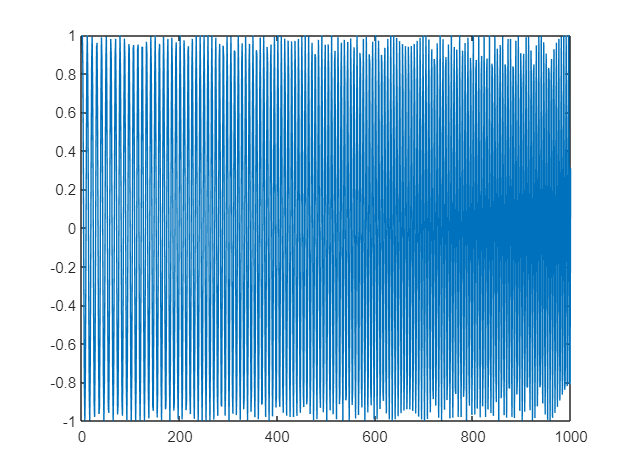

plot(chirp_pulse);

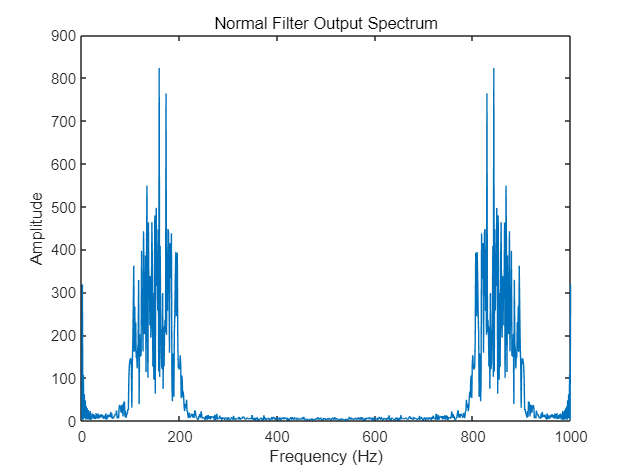

% 绘制发送信号和接收到的回波信号
plot(frequencies_chirp, abs(output_normal_fft));
title('Normal Filter Output Spectrum');
xlabel('Frequency (Hz)');
ylabel('Amplitude');

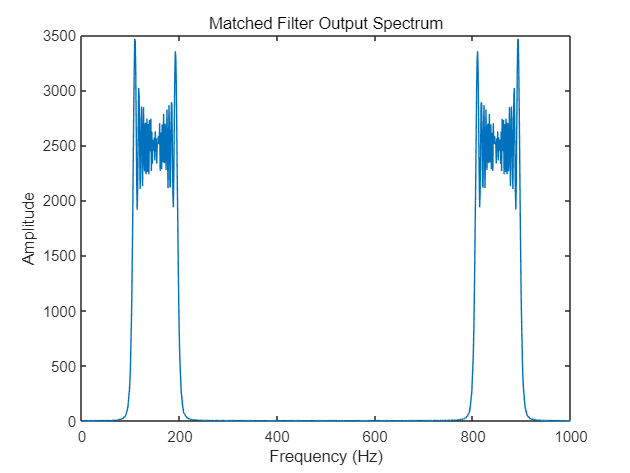


plot(frequencies_chirp, abs(output_chirp_fft));
title('Matched Filter Output Spectrum');
xlabel('Frequency (Hz)');
ylabel('Amplitude');

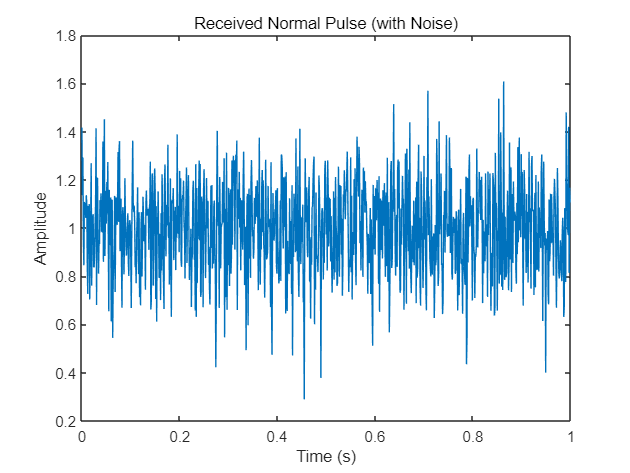


plot(t, received_normal);
title('Received Normal Pulse (with Noise)');
xlabel('Time (s)');
ylabel('Amplitude');

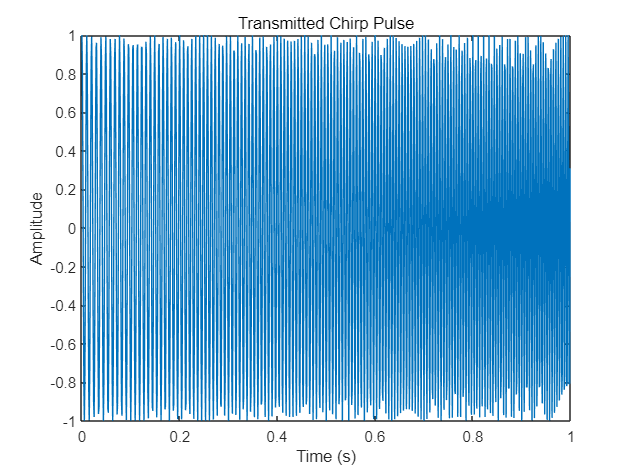


plot(t, chirp_pulse);
title('Transmitted Chirp Pulse');
xlabel('Time (s)');
ylabel('Amplitude');

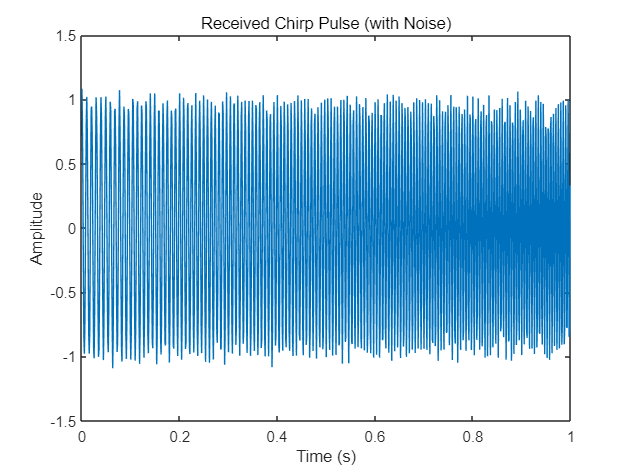


plot(t, received_chirp);
title('Received Chirp Pulse (with Noise)');
xlabel('Time (s)');
ylabel('Amplitude');

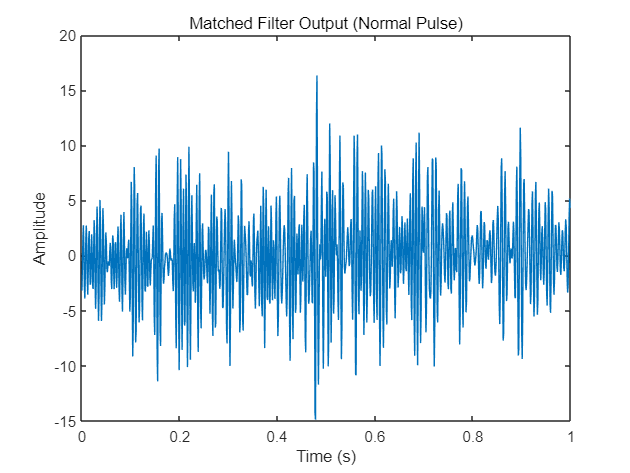


% 绘制匹配滤波器处理后的输出
plot(t, output_normal);
title('Matched Filter Output (Normal Pulse)');
xlabel('Time (s)');
ylabel('Amplitude');

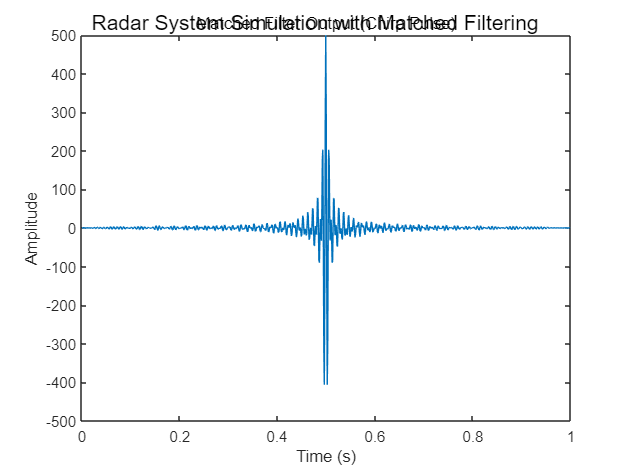


plot(t, output_chirp);
title('Matched Filter Output (Chirp Pulse)');
xlabel('Time (s)');
ylabel('Amplitude');

sgtitle('Radar System Simulation with Matched Filtering');